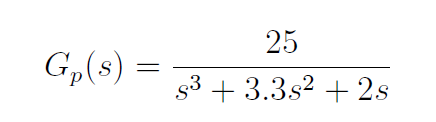

% syms t f H s
s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



Ga=0.0095

Ga = 0.0095

Gp=Ga*(25)/(s^3+3.3*s^2+2*s)

Gp =
 
        0.2375
  -------------------
  s^3 + 3.3 s^2 + 2 s
 
Continuous-time transfer function.



Gs=1

Gs = 1

Gr=1 

Gr = 1

Gd=1

Gd = 1


Kc=3.75;


Rz=1;
R_lag=1;

% Rz=(1+s/1);
% R_lag=(1+s/(4.21*0.015))/(1+s/0.015);


Gc=Kc/s*Rz*R_lag;


L=(Gc*Gp*Gs*Gf*Ga)

L =
 
        0.008461
  ---------------------
  s^4 + 3.3 s^3 + 2 s^2
 
Continuous-time transfer function.



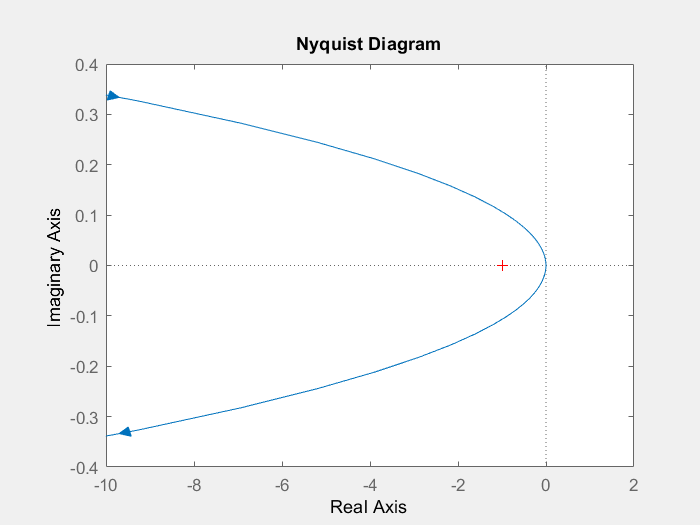

Tp=1.078;
Sp=1.393;
nyquist(L)


% omega =logspace(-4,6,1000);
% nichols(L,omega)
% hold on
% myngridst(Tp,Sp)
% hold off

% su(L,Tp,Sp)


